bound = 20;

map_struct = open("matlabOccupancyMap.mat");

map = map_struct.map; 
show (map)
 hold on
 
 Re = 1:0.1:3;
Re_(1:21) = 15;
Re__ = [Re_;Re];
obs_Re = transpose(Re__);
setOccupancy(map, obs_Re, 1)
show (map)

S = 4:0.1:5;
S_ = 13:0.1:14;
S__ = [S;S_];
obs_1 = transpose(S__);
setOccupancy(map, obs_1, 1)
show(map)

inflate(map,0.5)
show(map)

# kuch b

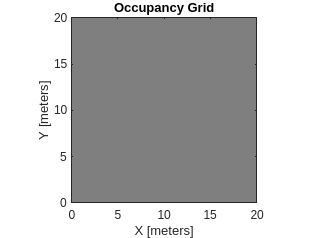


clc;
clear;
close all;


 node = ros2node('MATLAB');
 velocityPub = ros2publisher(node, "/position", "geometry_msgs/Point");
 msg = ros2message(velocityPub);

nRbt = 3;
nOrient = 2;
nIter = 100;
bound = 20;
d = 1; %step

% parameters
a = 2;
adamp = a/nIter;
dim = 1;
varSize = [1 dim];
% CostFunction = @(x) Sphere(x);

ray_lngth = 1.5; % max_range value in the paper

%value delta x, delta y 
y_up = 1;
y_down = -1;
y_stay = 0;
x_right = 1;
x_left = -1;
x_stay = 0;

Vrobot = 1;

anglesClsion = [pi/2,pi/4,0,7*pi/4,3*pi/2,5*pi/4,pi,3*pi/4];
thresholdClsionDttn = 0.9; %threshold of collition detection
maxrangeClsion = 2; %maxrange to detect collition


  map = robotics.OccupancyGrid(bound,bound,15); %resolution is the number of pixels in one cell; no needs to consider it below
 show (map);
hold on

%%
cntx = bound/2;
cnty = bound/2;
s = cnty/0.1;
A(1,s) = cntx-1;
A(1:s) = cntx;
B = cnty:0.1:bound-0.1;
C = [A; B];
C = transpose(C);
A = A/2.5;
D = [B; A];
D = transpose(D);
% q = (bound/0.1) - 10;
q = (bound/0.1);
E(1,q) = bound-1;
E(1:q) = 0.1;
I(1,q) = bound-1;
I(1:q) = bound-0.1;
% F = 1:0.1:bound-0.1;
F = 0:0.1:bound-0.1;
H = [E;F];
H = transpose(H);
G = [I;F];
G = transpose(G);
J = [F;I];
J = transpose(J);
W = [F;E];
W = transpose(W);
d_ = 0;
S = 15:0.1:20;
S_(1:51) = 5;
S__ = [S;S_];
obs_1 = transpose(S__);
Y = 0:0.1:2;
Y_(1:21) = 14;
Y__ = [Y;Y_];
obs_2 = transpose(Y__);
T(1:21) = 6;
T_ = 6:0.1:8;
T__ = [T;T_];
obs_3 = transpose(T__);

Z(1:21) = 15;
Z_ = 11:0.1:13;
Z__ = [Z;Z_];
obs_4 = transpose(Z__);



O(1:21) = 16;
O_ = 15:0.1:17;
O__ = [O;O_];
obs_7 = transpose(O__);

X(1:21) = 4;
X_ = 15:0.1:17;
X__ = [X;X_];
obs_5 = transpose(X__);

R = 7:0.1:9;
R_(1:21) = 1;
R__ = [R;R_];
obs_8 = transpose(R__);

T = 12:0.1:16;
T_ = 4:0.1:8;
T__ = [T;T_];
obs_33 = transpose(T__);




S = 4:0.1:7;
S_ = 17:0.1:20;
S__ = [S;S_];
obs_11 = transpose(S__);

 setOccupancy(map, obs_11, 1);
 
% %setOccupancy(map, obs_33, 1)
 %setOccupancy(map, W, 1)


setOccupancy(map, obs_5, 1)% upper

setOccupancy(map, obs_7, 1) % upper



## MUneeb Obstacles



A = 1:0.1:4;
A_ = 12:0.1:15;
A__ = [A;A_];
obs_50 = transpose(A__);
setOccupancy(map, obs_50, 1)

B = 7:0.1:10;
B_ = 17:0.1:20;
B__ = [B; B_];
B__(2,:) = flip(B__(2,:));
obs_51 = transpose(B__);
setOccupancy(map, obs_51, 1);

C = 10:0.1:13;
C_ = 17:0.1:20;
C__ = [C;C_];
obs_52 = transpose(C__);
setOccupancy(map, obs_52, 1);


D = 13:0.1:16;
D_ = 17:0.1:20;
D__ = [D; D_];
D__(2,:) = flip(D__(2,:));
obs_53 = transpose(D__);
setOccupancy(map, obs_53, 1);

E = 16:0.1:19;
E_ = 12:0.1:15;
E__ = [E;E_];
E__(2,:) = flip(E__(2,:));
obs_54 = transpose(E__);
setOccupancy(map, obs_54, 1)


F = 5:0.1:10;
F_ = 0:0.1:5;
F__ = [F;F_];
F__(2,:) = flip(F__(2,:));
obs_55 = transpose(F__);
setOccupancy(map, obs_55, 1)

K = 10:0.1:15;
K_ = 0:0.1:5;
K__ = [K;K_];
obs_56 = transpose(K__);
setOccupancy(map, obs_56, 1);

L(1:11) = 5;
L_ = 5:0.1:6;
L__ = [L;L_];
obs_57 = transpose(L__);
setOccupancy(map, obs_57, 1)

N(1:11) = 15;
N_ = 5:0.1:6;
N__ = [N;N_];
obs_58 = transpose(N__);
setOccupancy(map, obs_58, 1)

T = 15:0.1:19;
T_ = 6:0.1:10;
T__ = [T;T_];
obs_34 = transpose(T__);
setOccupancy(map, obs_34, 1);

P = 1:0.1:5;
P_ = 6:0.1:10;
P__ = [P;P_];
P__(2,:) = flip(P__(2,:));
obs_59 = transpose(P__);
setOccupancy(map, obs_59, 1)

X(1:21) = 1;
X_ = 10:0.1:12;
X__ = [X;X_];
obs_60 = transpose(X__);
setOccupancy(map, obs_60, 1)

X(1:21) = 19    ;
X_ = 10:0.1:12;
X__ = [X;X_];
obs_61 = transpose(X__);
setOccupancy(map, obs_61, 1)
%MIDDLE

M(1:2) = 6;
M_ = 11:0.1:11.1;
M__ = [M;M_];
obs_62 = transpose(M__);
setOccupancy(map, obs_62, 1) 

M(1:2) = 10;
M_ = 11:0.1:11.1;
M__ = [M;M_];
obs_63 = transpose(M__);
setOccupancy(map, obs_63, 1) 

M(1:2) = 14;
M_ = 11:0.1:11.1;
M__ = [M;M_];
obs_63 = transpose(M__);
setOccupancy(map, obs_63, 1) 

%UPPER

M(1:2) = 6;
M_ = 14:0.1:14.1;
M__ = [M;M_];
obs_64 = transpose(M__);
setOccupancy(map, obs_64, 1) 

M(1:2) = 10;
M_ = 14:0.1:14.1;
M__ = [M;M_];
obs_65 = transpose(M__);
setOccupancy(map, obs_65, 1) 

M(1:2) = 14;
M_ = 14:0.1:14.1;
M__ = [M;M_];
obs_66 = transpose(M__);
setOccupancy(map, obs_66, 1) 

%LOWER 

M(1:2) = 6;
M_ = 8:0.1:8.1;
M__ = [M;M_];
obs_67 = transpose(M__);
setOccupancy(map, obs_67, 1) 

M(1:2) = 10;
M_ = 8:0.1:8.1;
M__ = [M;M_];
obs_68 = transpose(M__);
setOccupancy(map, obs_68, 1) 

M(1:2) = 14;
M_ = 8:0.1:8.1;
M__ = [M;M_];
obs_69 = transpose(M__);
setOccupancy(map, obs_69, 1) 


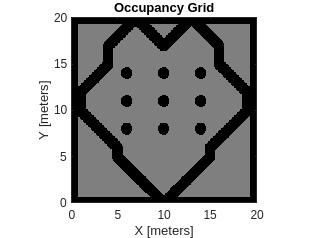


% % % upper vertical
% setOccupancy(map, C, 1)

% H left vertical
setOccupancy(map, H, 1)
% G right vertical
setOccupancy(map, G, 1)
% J upper horizontal
setOccupancy(map, J, 1)
setOccupancy(map, W, 1)

 %setOccupancy(map, obs_1, 1)
%% tunnel obstacle
% right horizontal
%setOccupancy(map, D, 1)
inflate(map,0.5)

show(map)

## code

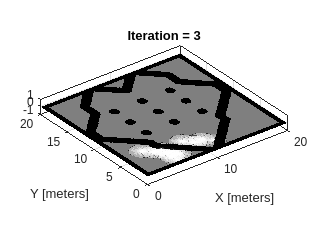

ans =      3     5     0


     1



     1



     1



     2



     1



     3



Iteration = 1


Selected candidates


Robot 1 selected alpha position


Robot 2 selected beta position


Robot 3 selected alpha position


Parameters: G1 = 0.47253 G2 = 1.98 QF = 1 a = 2


ans =      4     4


Iteration = 2


Selected candidates


Robot 1 selected alpha position


Robot 2 selected beta position
Robot 3 selected beta position


Parameters: G1 = 0.99078 G2 = 1.98 QF = 1 a = 2


ans =      5     4


Iteration = 3


Selected candidates


Robot 1 selected alpha position
Robot 2 selected alpha position


Robot 3 selected beta position


Parameters: G1 = 0.041683 G2 = 1.9602 QF = 1 a = 1.98


ans =      6     3


Index in position 2 is invalid. Array indices must be positive integers or logical values.

%% structure 

ranges = ray_lngth*ones(100,1); % 1.5 cells of range sensor beam
angles = linspace(3.14, -3.13, 100);
% angles = linspace(2*pi, 100);
maxrange = 5;
gridmap_arr_empty.Itertn.map = [];
gridmap_arr = repmat(gridmap_arr_empty,nRbt,1);


robot_empty.Itertn.Cost = [];
robot_empty.Itertn.Pose = [];
robot_empty.Itertn.V1.V1xy = [];
robot_empty.Itertn.V2.V2xy = [];
robot_empty.Itertn.V3.V3xy = [];
robot_empty.Itertn.V4.V4xy = [];
robot_empty.Itertn.V5.V5xy = [];
robot_empty.Itertn.V6.V6xy = [];
robot_empty.Itertn.V7.V7xy = [];
robot_empty.Itertn.V8.V8xy = [];
robot_empty.Itertn.V9.V9xy = [];
robot_empty.Itertn.V1.V1cost = [];
robot_empty.Itertn.V2.V2cost = [];
robot_empty.Itertn.V3.V3cost = [];
robot_empty.Itertn.V4.V4cost = [];
robot_empty.Itertn.V5.V5cost = [];
robot_empty.Itertn.V6.V6cost = [];
robot_empty.Itertn.V7.V7cost = [];
robot_empty.Itertn.V8.V8cost = [];
robot_empty.Itertn.V8.V9cost = [];
robot_empty.Itertn.MinCost.Value = [];
robot_empty.Itertn.MinCost.Index = [];
robot_empty.Itertn.MinCost.Vxy = [];
robot_empty.Itertn.V1.V1Utility = [];
robot_empty.Itertn.V2.V2Utility = [];
robot_empty.Itertn.V3.V3Utility = [];
robot_empty.Itertn.V4.V4Utility = [];
robot_empty.Itertn.V5.V5Utility = [];
robot_empty.Itertn.V6.V6Utility = [];
robot_empty.Itertn.V7.V7Utility = [];
robot_empty.Itertn.V8.V8Utility = [];
robot_empty.Itertn.V9.V9Utility = [];
robot_empty.Itertn.V1.V1Vbest = [];
robot_empty.Itertn.V2.V2Vbest = [];
robot_empty.Itertn.V3.V3Vbest = [];
robot_empty.Itertn.V4.V4Vbest = [];
robot_empty.Itertn.V5.V5Vbest = [];
robot_empty.Itertn.V6.V6Vbest = [];
robot_empty.Itertn.V7.V7Vbest = [];
robot_empty.Itertn.V8.V8Vbest = [];
robot_empty.Itertn.V9.V9Vbest = [];
robot_empty.Itertn.V1.V1Index = [];
robot_empty.Itertn.V2.V2Index = [];
robot_empty.Itertn.V3.V3Index = [];
robot_empty.Itertn.V4.V4Index = [];
robot_empty.Itertn.V5.V5Index = [];
robot_empty.Itertn.V6.V6Index = [];
robot_empty.Itertn.V7.V7Index = [];
robot_empty.Itertn.V8.V8Index = [];
robot_empty.Itertn.V9.V9Index = [];
robot_empty.Itertn.MaxUtility.Value = [];
robot_empty.Itertn.MaxUtility.Index = [];
robot_empty.Itertn.MaxUtility.Uxy = [];
obstacle = [];
V_empty.Itertn.V = [];
Vblock_empty.Itertn.V = [];

robots = repmat(robot_empty, nRbt, 1);

V = repmat(V_empty, nRbt, 1);
Vblock = repmat(Vblock_empty, nRbt, 1);

Utility = ones(bound);

aquila_empty.Itertn.alpha.Position = [];
aquila_empty.Itertn.alpha.Cost = [];
aquila_empty.Itertn.alpha.Index = [];
aquila_empty.Itertn.beta.Position = [];
aquila_empty.Itertn.beta.Cost = [];
aquila_empty.Itertn.beta.Index = [];
aquila_empty.Itertn.gamma.Position = [];
aquila_empty.Itertn.gamma.Cost = [];
aquila_empty.Itertn.gamma.Index = [];
aquilaX_empty.Itertn.Pairs.X = [];
aquilaX_empty.Itertn.Pairs.Combination = [];
aquilaX_empty.Itertn.Pairs.Cost = [];
aquilaX = repmat(aquilaX_empty,nRbt,1);
aquila = repmat(aquila_empty,nRbt,1);
% Utility = rand(20,bound);
% %% obstacle array
% for i = 1:bound
%     for j = 1:bound
%         obstacle(
%     end
% end
counter = 1;

for i = 1:bound
    for j = 1:bound
     
        occ = getOccupancy(map, [i, j]);
        if occ > 0.8000
            obstacle(counter, :) = [i, j];
            counter = counter + 1;
        end
    end
    
end

% for row = 2:bound-2
%     for column = 2:bound-2
%         Utility_total =  Utility_total + Utility(row, column);
%     end
% end
% Utility_total = Utility_total - 30;

%% initialization in Itertn 1
for i=1
    for j=1:nRbt
        if j==1
%             robots(j).Itertn(i).Pose = [3,5];
            robots(j).Itertn(i).Pose = [3,5,0];
        end
        if j==2
%             robots(j).Itertn(i).Pose = [5,4];
             robots(j).Itertn(i).Pose = [5,3,0];
        end
        if j==3
%             robots(j).Itertn(i).Pose = [7,4];
             robots(j).Itertn(i).Pose = [8,4,0];
        end
        robots(j).Itertn(i).Cost = [0, 0, 0, 0, 0, 0, 0, 0, 1];
        robots(j).Itertn(i).MaxUtility.Uxy = [0,0];
        robots(j).Itertn(i).MinCost.Vxy = [0,0];
        robots(j).Itertn(i).V1.V1Index = 1;
        robots(j).Itertn(i).V2.V2Index = 2;
        robots(j).Itertn(i).V3.V3Index = 3;
        robots(j).Itertn(i).V4.V4Index = 4;
        robots(j).Itertn(i).V5.V5Index = 5;
        robots(j).Itertn(i).V6.V6Index = 6;
        robots(j).Itertn(i).V7.V7Index = 7;
        robots(j).Itertn(i).V8.V8Index = 8;
        robots(j).Itertn(i).V9.V9Index = 9;
        
        robots(j).Itertn(i).V1.V1Utility = 1;
        robots(j).Itertn(i).V2.V2Utility = 1;
        robots(j).Itertn(i).V3.V3Utility = 1;
        robots(j).Itertn(i).V4.V4Utility = 1;
        robots(j).Itertn(i).V5.V5Utility = 1;
        robots(j).Itertn(i).V6.V6Utility = 1;
        robots(j).Itertn(i).V7.V7Utility = 1;
        robots(j).Itertn(i).V8.V8Utility = 1;
        robots(j).Itertn(i).V9.V9Utility = 1;
        
        robots(j).Itertn.V1.V1Vbest = 0;
        robots(j).Itertn.V2.V2Vbest = 0;
        robots(j).Itertn.V3.V3Vbest = 0;
        robots(j).Itertn.V4.V4Vbest = 0;
        robots(j).Itertn.V5.V5Vbest = 0;
        robots(j).Itertn.V6.V6Vbest = 0;
        robots(j).Itertn.V7.V7Vbest = 0;
        robots(j).Itertn.V8.V8Vbest = 0;
        robots(j).Itertn.V9.V9Vbest = 0;
        
        
        
        for row = 1:21
            for col = 1:21
                gridmap_arr(j).Itertn(i).map(row,col) = getOccupancy(map,[row-1,col-1]);

            end
        end

        

        x = robots(j).Itertn(i).Pose(1,1);
        y = robots(j).Itertn(i).Pose(1,2);
%         thi = robots(j).Itertn(i).Pose(1,3);        
        insertRay(map,[x,y,0],ranges,angles,maxrange); %shows path of robot
        hold on
        
        color = ['r','b','y'];
        
        if j==1
            plotTrVec = [];
            plot(robots(j).Itertn(i).Pose(1,1),robots(j).Itertn(i).Pose(1,2),'color',color(1),'marker','s');
            hold on
        elseif j==2
            plot(robots(j).Itertn(i).Pose(1,1),robots(j).Itertn(i).Pose(1,2),'color',color(2),'marker','s');
            hold on
        elseif j==3
            plot(robots(j).Itertn(i).Pose(1,1),robots(j).Itertn(i).Pose(1,2),'color',color(3),'marker','s');
            hold on
        end
        show(map)
        grid on
        hold on
        view(3)
    end
end

       

k_ = 1;

% 
%% Main source
% 
%Cost
hold on
% try 

    for i=1:nIter
                robots(1).Itertn(i).Pose

               msg.x =  linearTransform(robots(1).Itertn(i).Pose(1),0,20,-1.25,5);
               % 
               msg.y =  linearTransform(robots(1).Itertn(i).Pose(2),0,20,-2.44,3.36);

               % msg.x =  linearTransform(robots(1).Itertn(i).Pose(1),0,20,-8.86,9.8); %Aquila Map

               % msg.y =  linearTransform(robots(1).Itertn(i).Pose(2),0,20,-8.86,10.08); % Aquila Map
               % msg.x = robots(1).Itertn(i).Pose(1);
                 % msg.y = robots(1).Itertn(i).Pose(2);
   

            send(velocityPub, msg);
            pause(1) %wait for robot to reach destination
        val = 1;
        for j=1:nRbt       
    %         if i ~= 1
                x = robots(j).Itertn(i).Pose(1,1);
                y = robots(j).Itertn(i).Pose(1,2);
                hold on
                insertRay(map,[x,y,0],ranges,angles,maxrange);
    %         end


            [V1,V2,V3,V4,V5,V6,V7,V8,V9] = gridsOrientation(x,y);
            V(j).Itertn(i).V = [V1;V2;V3;V4;V5;V6;V7;V8;V9];
            robots(j).Itertn(i).V1.V1Index = 1;
            robots(j).Itertn(i).V2.V2Index = 2;
            robots(j).Itertn(i).V3.V3Index = 3;
            robots(j).Itertn(i).V4.V4Index = 4;
            robots(j).Itertn(i).V5.V5Index = 5;
            robots(j).Itertn(i).V6.V6Index = 6;
            robots(j).Itertn(i).V7.V7Index = 7;
            robots(j).Itertn(i).V8.V8Index = 8;
            robots(j).Itertn(i).V9.V9Index = 9;


            robots(j).Itertn(i).V1.V1xy = V1;
            robots(j).Itertn(i).V2.V2xy = V2;
            robots(j).Itertn(i).V3.V3xy = V3;
            robots(j).Itertn(i).V4.V4xy = V4;
            robots(j).Itertn(i).V5.V5xy = V5;
            robots(j).Itertn(i).V6.V6xy = V6;
            robots(j).Itertn(i).V7.V7xy = V7;
            robots(j).Itertn(i).V8.V8xy = V8;
            robots(j).Itertn(i).V9.V9xy = V9; 


            % cost
            Vbst =  0;
            if i == 1
                robots(j).Itertn(i).V1.V1cost = robots(j).Itertn(i).Cost(1,1) + (pdist([x,y;x,y+1],'euclidean'))*(getOccupancy(map,V1));
                robots(j).Itertn(i).V2.V2cost = robots(j).Itertn(i).Cost(1,2) + (pdist([x,y;x+1,y+1],'euclidean'))*(getOccupancy(map,V2));
                robots(j).Itertn(i).V3.V3cost = robots(j).Itertn(i).Cost(1,3) + (pdist([x,y;x+1,y],'euclidean'))*(getOccupancy(map,V3));
                robots(j).Itertn(i).V4.V4cost = robots(j).Itertn(i).Cost(1,4) + (pdist([x,y;x+1,y-1],'euclidean'))*(getOccupancy(map,V4));
                robots(j).Itertn(i).V5.V5cost = robots(j).Itertn(i).Cost(1,5) + (pdist([x,y;x,y-1],'euclidean'))*(getOccupancy(map,V5));
                robots(j).Itertn(i).V6.V6cost = robots(j).Itertn(i).Cost(1,6) + (pdist([x,y;x-1,y-1],'euclidean'))*(getOccupancy(map,V6));
                robots(j).Itertn(i).V7.V7cost = robots(j).Itertn(i).Cost(1,7) + (pdist([x,y;x-1,y],'euclidean'))*(getOccupancy(map,V7));
                robots(j).Itertn(i).V8.V8cost = robots(j).Itertn(i).Cost(1,8) + (pdist([x,y;x-1,y+1],'euclidean'))*(getOccupancy(map,V8));
                robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i).Cost(1,9) + (pdist([x,y;x,y],'euclidean'))*(getOccupancy(map,V9));

                robots(j).Itertn(i).Cost = [robots(j).Itertn(i).V1.V1cost, robots(j).Itertn(i).V2.V2cost, robots(j).Itertn(i).V3.V3cost, robots(j).Itertn(i).V4.V4cost,...
                    robots(j).Itertn(i).V5.V5cost, robots(j).Itertn(i).V6.V6cost, robots(j).Itertn(i).V7.V7cost, robots(j).Itertn(i).V8.V8cost, robots(j).Itertn(i).V9.V9cost];

                [robots(j).Itertn(i).MinCost.Value, robots(j).Itertn(i).MinCost.Index] = min(robots(j).Itertn(i).Cost(robots(j).Itertn(i).Cost>0));
                disp(i)
                disp(j)
                U1 = Utility(robots(j).Itertn(i).V1.V1xy(1,1), robots(j).Itertn(i).V1.V1xy(1,2)) - robots(j).Itertn(i).Cost(1,1);
                U2 = Utility(robots(j).Itertn(i).V2.V2xy(1,1), robots(j).Itertn(i).V2.V2xy(1,2)) - robots(j).Itertn(i).Cost(1,2);
                U3 = Utility(robots(j).Itertn(i).V3.V3xy(1,1), robots(j).Itertn(i).V3.V3xy(1,2)) - robots(j).Itertn(i).Cost(1,3);
                U4 = Utility(robots(j).Itertn(i).V4.V4xy(1,1), robots(j).Itertn(i).V4.V4xy(1,2)) - robots(j).Itertn(i).Cost(1,4);
                U5 = Utility(robots(j).Itertn(i).V5.V5xy(1,1), robots(j).Itertn(i).V5.V5xy(1,2)) - robots(j).Itertn(i).Cost(1,5);
                U6 = Utility(robots(j).Itertn(i).V6.V6xy(1,1), robots(j).Itertn(i).V6.V6xy(1,2)) - robots(j).Itertn(i).Cost(1,6);
                U7 = Utility(robots(j).Itertn(i).V7.V7xy(1,1), robots(j).Itertn(i).V7.V7xy(1,2)) - robots(j).Itertn(i).Cost(1,7);
                U8 = Utility(robots(j).Itertn(i).V8.V8xy(1,1), robots(j).Itertn(i).V8.V8xy(1,2)) - robots(j).Itertn(i).Cost(1,8);

                allUtility = [U1,U2,U3,U4,U5,U6,U7,U8];
                [robots(j).Itertn(i).MaxUtility.Value, robots(j).Itertn(i).MaxUtility.Index] = max(allUtility);

                Vblock(j).Itertn(i).V = [0,0];
            end
            if i>1
                val = 1;
                if j==2 || j==3
                    k_ = 1;
                    Vblock(j).Itertn(i).V = [0,0];
                    for i_=1:9  
    %                     Vblock(j).Itertn(i).V = [0,0];
                        for j_=1:9

                            if V(j).Itertn(i).V(i_,1)==V(j-1).Itertn(i).V(j_,1) && V(j).Itertn(i).V(i_,2)==V(j-1).Itertn(i).V(j_,2)
    %                             disp([V(j).Itertn(i).V(i_,1),V(j).Itertn(i).V(i_,2)]);
                                Vblock(j).Itertn(i).V(k_,:) = [V(j).Itertn(i).V(i_,1), V(j).Itertn(i).V(i_,2)];
                                k_ = k_ + 1;

                            end
                            if j == 3
                                   if V(3).Itertn(i).V(i_,1)==V(1).Itertn(i).V(j_,1) && V(3).Itertn(i).V(i_,2)==V(1).Itertn(i).V(j_,2)
    %                                    disp([V(j).Itertn(i).V(i_,1),V(j).Itertn(i).V(i_,2)]);
                                       Vblock(j).Itertn(i).V(k_,:) = [V(j).Itertn(i).V(i_,1), V(j).Itertn(i).V(i_,2)];
                                       k_ = k_ + 1;
                                   end
                            end




                        end

                    end
                else
                    Vblock(j).Itertn(i).V = [0,0];
                end




                if robots(j).Itertn(i-1).MaxUtility.Index == 1
                    [m,n] = size(Vblock(j).Itertn(i).V);
                    for cnt = 1:m  

                        if V1(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V1(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V1.V1cost = (pdist([x,y;x,y+1],'euclidean'))*0.7;
                            break;
                        else
                            robots(j).Itertn(i).V1.V1cost = (pdist([x,y;x,y+1],'euclidean'))*(getOccupancy(map,V1));

                        end
                    end

                    for cnt = 1:m               
                        if V2(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V2(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V2.V2cost = (pdist([x,y;x+1,y+1],'euclidean'))*0.7;
                            break;
                        else
                            robots(j).Itertn(i).V2.V2cost = (pdist([x,y;x+1,y+1],'euclidean'))*(getOccupancy(map,V2));
                        end
                    end

                    for cnt = 1:m               
                        if V3(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V3(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V3.V3cost = robots(j).Itertn(i-1).Cost(1,2) + (pdist([x,y;x+1,y],'euclidean'))*0.7;
                            break;
                        else
                            robots(j).Itertn(i).V3.V3cost = robots(j).Itertn(i-1).Cost(1,2) + (pdist([x,y;x+1,y],'euclidean'))*(getOccupancy(map,V3));
                        end
                    end

                    for cnt = 1:m               
                        if V4(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V4(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V4.V4cost = robots(j).Itertn(i-1).Cost(1,3) + (pdist([x,y;x+1,y-1],'euclidean'))*0.7;
                            break;
                        else
                            robots(j).Itertn(i).V4.V4cost = robots(j).Itertn(i-1).Cost(1,3) + (pdist([x,y;x+1,y-1],'euclidean'))*(getOccupancy(map,V4));
                        end
                    end

                    for cnt = 1:m               
                        if V5(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V5(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V5.V5cost = robots(j).Itertn(i-1).Cost(1,9) + (pdist([x,y;x,y-1],'euclidean'))*0.7;
                            break;
                        else
                            robots(j).Itertn(i).V5.V5cost = robots(j).Itertn(i-1).Cost(1,9) + (pdist([x,y;x,y-1],'euclidean'))*(getOccupancy(map,V5));
                        end
                    end

                    for cnt = 1:m               
                        if V6(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V6(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V6.V6cost = robots(j).Itertn(i-1).Cost(1,7) + (pdist([x,y;x-1,y-1],'euclidean'))*0.7;
                            break;
                        else
                            robots(j).Itertn(i).V6.V6cost = robots(j).Itertn(i-1).Cost(1,7) + (pdist([x,y;x-1,y-1],'euclidean'))*(getOccupancy(map,V6));
                        end
                    end

                   for cnt = 1:m               
                        if V7(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V7(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V7.V7cost = robots(j).Itertn(i-1).Cost(1,8) + (pdist([x,y;x-1,y],'euclidean'))*0.7;
                            break;
                        else
                            robots(j).Itertn(i).V7.V7cost = robots(j).Itertn(i-1).Cost(1,8) + (pdist([x,y;x-1,y],'euclidean'))*(getOccupancy(map,V7));
                        end
                   end

                   for cnt = 1:m               
                        if V8(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V8(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V8.V8cost = (pdist([x,y;x-1,y+1],'euclidean'))*0.7;
                            break;
                        else
                            robots(j).Itertn(i).V8.V8cost = (pdist([x,y;x-1,y+1],'euclidean'))*(getOccupancy(map,V8));
                        end
                   end

                   for cnt = 1:m               
                        if V9(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V9(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i-1).Cost(1,1) + (pdist([x,y;x,y],'euclidean'))*0.7;
                            break;
                        else
                            robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i-1).Cost(1,1) + (pdist([x,y;x,y],'euclidean'))*(getOccupancy(map,V9));
                        end
                    end

                end
                if robots(j).Itertn(i-1).MaxUtility.Index == 2
                    [m,n] = size(Vblock(j).Itertn(i).V);
                    for cnt = 1:m               
                        if V1(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V1(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V1.V1cost = (pdist([x,y;x,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V1.V1cost = (pdist([x,y;x,y+1],'euclidean'))*(getOccupancy(map,V1));
                        end
                    end
                    for cnt = 1:m               
                        if V2(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V2(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V2.V2cost = (pdist([x,y;x+1,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V2.V2cost = (pdist([x,y;x+1,y+1],'euclidean'))*(getOccupancy(map,V2));
                        end
                    end
                    for cnt = 1:m               
                        if V3(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V3(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V3.V3cost = (pdist([x,y;x+1,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V3.V3cost = (pdist([x,y;x+1,y],'euclidean'))*(getOccupancy(map,V3));
                        end
                    end

                    for cnt = 1:m               
                        if V4(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V4(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V4.V4cost = (pdist([x,y;x+1,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V4.V4cost = (pdist([x,y;x+1,y-1],'euclidean'))*(getOccupancy(map,V4));
                        end
                    end

                    for cnt = 1:m               
                        if V5(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V5(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V5.V5cost = robots(j).Itertn(i-1).Cost(1,3) + (pdist([x,y;x,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V5.V5cost = robots(j).Itertn(i-1).Cost(1,3) + (pdist([x,y;x,y-1],'euclidean'))*(getOccupancy(map,V5));
                        end
                    end
                    for cnt = 1:m               
                        if V6(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V6(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V6.V6cost = robots(j).Itertn(i-1).Cost(1,9) + (pdist([x,y;x-1,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V6.V6cost = robots(j).Itertn(i-1).Cost(1,9) + (pdist([x,y;x-1,y-1],'euclidean'))*(getOccupancy(map,V6));
                        end
                    end
                    for cnt = 1:m               
                        if V7(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V7(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V7.V7cost = robots(j).Itertn(i-1).Cost(1,1) + (pdist([x,y;x-1,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V7.V7cost = robots(j).Itertn(i-1).Cost(1,1) + (pdist([x,y;x-1,y],'euclidean'))*(getOccupancy(map,V7));
                        end
                    end
                    for cnt = 1:m               
                        if V8(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V8(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V8.V8cost = Vbst + (pdist([x,y;x-1,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V8.V8cost = Vbst + (pdist([x,y;x-1,y+1],'euclidean'))*(getOccupancy(map,V8));
                        end
                    end
                    for cnt = 1:m               
                        if V9(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V9(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i-1).Cost(1,2) + (pdist([x,y;x,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i-1).Cost(1,2) + (pdist([x,y;x,y],'euclidean'))*(getOccupancy(map,V9));
                        end
                    end
                end

                if robots(j).Itertn(i-1).MaxUtility.Index == 3
                    [m,n] = size(Vblock(j).Itertn(i).V);
                    for cnt = 1:m               
                        if V1(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V1(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V1.V1cost = robots(j).Itertn(i-1).Cost(1,2) + (pdist([x,y;x,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V1.V1cost = robots(j).Itertn(i-1).Cost(1,2) + (pdist([x,y;x,y+1],'euclidean'))*(getOccupancy(map,V1));
                        end
                    end

                    for cnt = 1:m                
                        if V2(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V2(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V2.V2cost = (pdist([x,y;x+1,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V2.V2cost = (pdist([x,y;x+1,y+1],'euclidean'))*(getOccupancy(map,V2));
                        end
                    end

                    for cnt = 1:m                
                        if V3(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V3(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V3.V3cost = (pdist([x,y;x+1,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V3.V3cost = (pdist([x,y;x+1,y],'euclidean'))*(getOccupancy(map,V3));
                        end
                    end

                    for cnt = 1:m                
                        if V4(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V4(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V4.V4cost = (pdist([x,y;x+1,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V4.V4cost = (pdist([x,y;x+1,y-1],'euclidean'))*(getOccupancy(map,V4));
                        end
                    end

                    for cnt = 1:m                
                        if V5(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V5(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V5.V5cost = robots(j).Itertn(i-1).Cost(1,4) + (pdist([x,y;x,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V5.V5cost = robots(j).Itertn(i-1).Cost(1,4) + (pdist([x,y;x,y-1],'euclidean'))*(getOccupancy(map,V5));
                        end
                    end

                    for cnt = 1:m                
                        if V6(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V6(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V6.V6cost = robots(j).Itertn(i-1).Cost(1,5) + (pdist([x,y;x-1,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V6.V6cost = robots(j).Itertn(i-1).Cost(1,5) + (pdist([x,y;x-1,y-1],'euclidean'))*(getOccupancy(map,V6));
                        end
                    end
                    for cnt = 1:m                
                        if V7(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V7(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V7.V7cost = robots(j).Itertn(i-1).Cost(1,9) + (pdist([x,y;x-1,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V7.V7cost = robots(j).Itertn(i-1).Cost(1,9) + (pdist([x,y;x-1,y],'euclidean'))*(getOccupancy(map,V7));
                        end
                    end
                    for cnt = 1:m                
                        if V8(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V8(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V8.V8cost = robots(j).Itertn(i-1).Cost(1,1) + (pdist([x,y;x-1,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V8.V8cost = robots(j).Itertn(i-1).Cost(1,1) + (pdist([x,y;x-1,y+1],'euclidean'))*(getOccupancy(map,V8));
                        end
                    end
                    for cnt = 1:m                
                        if V9(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V9(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i-1).Cost(1,3) + (pdist([x,y;x,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i-1).Cost(1,3) + (pdist([x,y;x,y],'euclidean'))*(getOccupancy(map,V9));
                        end
                    end
                end

                if robots(j).Itertn(i-1).MaxUtility.Index == 4
                    [m,n] = size(Vblock(j).Itertn(i).V);
                    for cnt = 1:m               
                        if V1(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V1(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V1.V1cost = robots(j).Itertn(i-1).Cost(1,3) + (pdist([x,y;x,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V1.V1cost = robots(j).Itertn(i-1).Cost(1,3) + (pdist([x,y;x,y+1],'euclidean'))*(getOccupancy(map,V1));
                        end
                    end
                    for cnt = 1:m               
                        if V2(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V2(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V2.V2cost = (pdist([x,y;x+1,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V2.V2cost = (pdist([x,y;x+1,y+1],'euclidean'))*(getOccupancy(map,V2));
                        end
                    end

                    for cnt = 1:m               
                        if V3(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V3(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V3.V3cost = (pdist([x,y;x+1,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V3.V3cost = (pdist([x,y;x+1,y],'euclidean'))*(getOccupancy(map,V3));
                        end
                    end

                    for cnt = 1:m               
                        if V4(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V4(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V4.V4cost = (pdist([x,y;x+1,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V4.V4cost = (pdist([x,y;x+1,y-1],'euclidean'))*(getOccupancy(map,V4));
                        end
                    end

                    for cnt = 1:m               
                        if V5(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V5(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V5.V5cost = (pdist([x,y;x,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V5.V5cost = (pdist([x,y;x,y-1],'euclidean'))*(getOccupancy(map,V5));
                        end
                    end

                    for cnt = 1:m               
                        if V6(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V6(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V6.V6cost = (pdist([x,y;x-1,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V6.V6cost = (pdist([x,y;x-1,y-1],'euclidean'))*(getOccupancy(map,V6));
                        end
                    end

                    for cnt = 1:m               
                        if V7(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V7(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V7.V7cost = robots(j).Itertn(i-1).Cost(1,5) + (pdist([x,y;x-1,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V7.V7cost = robots(j).Itertn(i-1).Cost(1,5) + (pdist([x,y;x-1,y],'euclidean'))*(getOccupancy(map,V7));
                        end
                    end

                   for cnt = 1:m               
                        if V8(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V8(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V8.V8cost = robots(j).Itertn(i-1).Cost(1,9) + (pdist([x,y;x-1,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V8.V8cost = robots(j).Itertn(i-1).Cost(1,9) + (pdist([x,y;x-1,y+1],'euclidean'))*(getOccupancy(map,V8));
                        end
                   end

                   for cnt = 1:m               
                        if V9(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V9(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i-1).Cost(1,4) + (pdist([x,y;x,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i-1).Cost(1,4) + (pdist([x,y;x,y],'euclidean'))*(getOccupancy(map,V9));
                        end
                    end

                end

                if robots(j).Itertn(i-1).MaxUtility.Index == 5
                    [m,n] = size(Vblock(j).Itertn(i).V);
                    for cnt = 1:m               
                        if V1(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V1(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V1.V1cost = robots(j).Itertn(i-1).Cost(1,9) + (pdist([x,y;x,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V1.V1cost = robots(j).Itertn(i-1).Cost(1,9) + (pdist([x,y;x,y+1],'euclidean'))*(getOccupancy(map,V1));
                        end
                    end

                    for cnt = 1:m               
                        if V2(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V2(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V2.V2cost = robots(j).Itertn(i-1).Cost(1,3) + (pdist([x,y;x+1,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V2.V2cost = robots(j).Itertn(i-1).Cost(1,3) + (pdist([x,y;x+1,y+1],'euclidean'))*(getOccupancy(map,V2));
                        end
                    end

                    for cnt = 1:m               
                        if V2(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V2(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V3.V3cost = robots(j).Itertn(i-1).Cost(1,4) + (pdist([x,y;x+1,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V3.V3cost = robots(j).Itertn(i-1).Cost(1,4) + (pdist([x,y;x+1,y],'euclidean'))*(getOccupancy(map,V3));
                        end
                    end

                    for cnt = 1:m               
                        if V3(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V3(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V3.V3cost = robots(j).Itertn(i-1).Cost(1,4) + (pdist([x,y;x+1,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V3.V3cost = robots(j).Itertn(i-1).Cost(1,4) + (pdist([x,y;x+1,y],'euclidean'))*(getOccupancy(map,V3));
                        end
                    end

                    for cnt = 1:m               
                        if V4(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V4(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V4.V4cost = (pdist([x,y;x+1,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V4.V4cost = (pdist([x,y;x+1,y-1],'euclidean'))*(getOccupancy(map,V4));
                        end
                    end

                    for cnt = 1:m               
                        if V5(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V5(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V5.V5cost = (pdist([x,y;x,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V5.V5cost = (pdist([x,y;x,y-1],'euclidean'))*(getOccupancy(map,V5));
                        end
                    end

                    for cnt = 1:m               
                        if V6(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V6(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V6.V6cost = (pdist([x,y;x-1,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V6.V6cost = (pdist([x,y;x-1,y-1],'euclidean'))*(getOccupancy(map,V6));
                        end
                    end

                    for cnt = 1:m               
                        if V7(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V7(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V7.V7cost = robots(j).Itertn(i-1).Cost(1,6) + (pdist([x,y;x-1,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V7.V7cost = robots(j).Itertn(i-1).Cost(1,6) + (pdist([x,y;x-1,y],'euclidean'))*(getOccupancy(map,V7));
                        end
                    end

                    for cnt = 1:m               
                        if V8(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V8(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V8.V8cost = robots(j).Itertn(i-1).Cost(1,7) + (pdist([x,y;x-1,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V8.V8cost = robots(j).Itertn(i-1).Cost(1,7) + (pdist([x,y;x-1,y+1],'euclidean'))*(getOccupancy(map,V8));
                        end
                    end

                    for cnt = 1:m               
                        if V9(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V9(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i-1).Cost(1,5) + (pdist([x,y;x,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i-1).Cost(1,5) + (pdist([x,y;x,y],'euclidean'))*(getOccupancy(map,V9));
                        end
                    end
                end

                if robots(j).Itertn(i-1).MaxUtility.Index == 6
                    [m,n] = size(Vblock(j).Itertn(i).V);
                    for cnt = 1:m               
                        if V1(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V1(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V1.V1cost = robots(j).Itertn(i-1).Cost(1,7) + (pdist([x,y;x,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V1.V1cost = robots(j).Itertn(i-1).Cost(1,7) + (pdist([x,y;x,y+1],'euclidean'))*(getOccupancy(map,V1));
                        end
                    end

                    for cnt = 1:m               
                        if V2(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V2(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V2.V2cost = robots(j).Itertn(i-1).Cost(1,9) + (pdist([x,y;x+1,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V2.V2cost = robots(j).Itertn(i-1).Cost(1,9) + (pdist([x,y;x+1,y+1],'euclidean'))*(getOccupancy(map,V2));
                        end
                    end

                    for cnt = 1:m               
                        if V3(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V3(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V3.V3cost = robots(j).Itertn(i-1).Cost(1,5) + (pdist([x,y;x+1,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V3.V3cost = robots(j).Itertn(i-1).Cost(1,5) + (pdist([x,y;x+1,y],'euclidean'))*(getOccupancy(map,V3));
                        end
                    end

                    for cnt = 1:m               
                        if V4(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V4(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V4.V4cost = (pdist([x,y;x+1,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V4.V4cost = (pdist([x,y;x+1,y-1],'euclidean'))*(getOccupancy(map,V4));
                        end
                    end

                    for cnt = 1:m               
                        if V5(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V5(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V5.V5cost = (pdist([x,y;x,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V5.V5cost = (pdist([x,y;x,y-1],'euclidean'))*(getOccupancy(map,V5));
                        end
                    end

                    for cnt = 1:m               
                        if V6(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V6(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V6.V6cost = (pdist([x,y;x-1,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V6.V6cost = (pdist([x,y;x-1,y-1],'euclidean'))*(getOccupancy(map,V6));
                        end
                    end

                    for cnt = 1:m               
                        if V7(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V7(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V7.V7cost = (pdist([x,y;x-1,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V7.V7cost = (pdist([x,y;x-1,y],'euclidean'))*(getOccupancy(map,V7));
                        end
                    end

                    for cnt = 1:m               
                        if V8(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V8(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V8.V8cost = (pdist([x,y;x-1,y+1],'euclidean'))*(getOccupancy(map,V8));
                        else
                            robots(j).Itertn(i).V8.V8cost = (pdist([x,y;x-1,y+1],'euclidean'))*(getOccupancy(map,V8));
                        end
                    end

                    for cnt = 1:m               
                        if V9(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V9(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i-1).Cost(1,6) + (pdist([x,y;x,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i-1).Cost(1,6) + (pdist([x,y;x,y],'euclidean'))*(getOccupancy(map,V9));
                        end
                    end

                end

                if robots(j).Itertn(i-1).MaxUtility.Index == 7
                    [m,n] = size(Vblock(j).Itertn(i).V);
                    for cnt = 1:m               
                        if V1(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V1(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V1.V1cost = robots(j).Itertn(i-1).Cost(1,8) + (pdist([x,y;x,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V1.V1cost = robots(j).Itertn(i-1).Cost(1,8) + (pdist([x,y;x,y+1],'euclidean'))*(getOccupancy(map,V1));
                        end
                    end

                    for cnt = 1:m               
                        if V2(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V2(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V2.V2cost = robots(j).Itertn(i-1).Cost(1,1) + (pdist([x,y;x+1,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V2.V2cost = robots(j).Itertn(i-1).Cost(1,1) + (pdist([x,y;x+1,y+1],'euclidean'))*(getOccupancy(map,V2));
                        end
                    end

                    for cnt = 1:m               
                        if V3(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V3(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V3.V3cost = robots(j).Itertn(i-1).Cost(1,9) + (pdist([x,y;x+1,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V3.V3cost = robots(j).Itertn(i-1).Cost(1,9) + (pdist([x,y;x+1,y],'euclidean'))*(getOccupancy(map,V3));
                        end
                    end

                    for cnt = 1:m               
                        if V4(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V4(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V4.V4cost = robots(j).Itertn(i-1).Cost(1,5) + (pdist([x,y;x+1,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V4.V4cost = robots(j).Itertn(i-1).Cost(1,5) + (pdist([x,y;x+1,y-1],'euclidean'))*(getOccupancy(map,V4));
                        end
                    end

                    for cnt = 1:m               
                        if V5(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V5(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V5.V5cost = robots(j).Itertn(i-1).Cost(1,6) + (pdist([x,y;x,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V5.V5cost = robots(j).Itertn(i-1).Cost(1,6) + (pdist([x,y;x,y-1],'euclidean'))*(getOccupancy(map,V5));
                        end
                    end

                    for cnt = 1:m               
                        if V6(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V6(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V6.V6cost = (pdist([x,y;x-1,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V6.V6cost = (pdist([x,y;x-1,y-1],'euclidean'))*(getOccupancy(map,V6));
                        end
                    end

                    for cnt = 1:m               
                        if V7(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V7(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V7.V7cost = (pdist([x,y;x-1,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V7.V7cost = (pdist([x,y;x-1,y],'euclidean'))*(getOccupancy(map,V7));
                        end
                    end

                    for cnt = 1:m               
                        if V8(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V8(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V8.V8cost = (pdist([x,y;x-1,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V8.V8cost = (pdist([x,y;x-1,y+1],'euclidean'))*(getOccupancy(map,V8));
                        end
                    end

                    for cnt = 1:m               
                        if V9(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V9(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i-1).Cost(1,7) + (pdist([x,y;x,y],'euclidean'))*0.9;
                        else
                            robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i-1).Cost(1,7) + (pdist([x,y;x,y],'euclidean'))*(getOccupancy(map,V9));
                        end
                    end

                end

                if robots(j).Itertn(i-1).MaxUtility.Index == 8
                    [m,n] = size(Vblock(j).Itertn(i).V);
                    for cnt = 1:m               
                        if V1(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V1(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V1.V1cost = (pdist([x,y;x,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V1.V1cost = (pdist([x,y;x,y+1],'euclidean'))*(getOccupancy(map,V1));
                        end
                    end

                    for cnt = 1:m               
                        if V2(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V2(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V2.V2cost = (pdist([x,y;x+1,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V2.V2cost = (pdist([x,y;x+1,y+1],'euclidean'))*(getOccupancy(map,V2));
                        end
                    end

                    for cnt = 1:m               
                        if V3(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V3(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V3.V3cost = robots(j).Itertn(i-1).Cost(1,1) + (pdist([x,y;x+1,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V3.V3cost = robots(j).Itertn(i-1).Cost(1,1) + (pdist([x,y;x+1,y],'euclidean'))*(getOccupancy(map,V3));
                        end
                    end

                    for cnt = 1:m               
                        if V4(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V4(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V4.V4cost = robots(j).Itertn(i-1).Cost(1,9) + (pdist([x,y;x+1,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V4.V4cost = robots(j).Itertn(i-1).Cost(1,9) + (pdist([x,y;x+1,y-1],'euclidean'))*(getOccupancy(map,V4));
                        end
                    end

                    for cnt = 1:m               
                        if V5(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V5(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V5.V5cost = robots(j).Itertn(i-1).Cost(1,7) + (pdist([x,y;x,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V5.V5cost = robots(j).Itertn(i-1).Cost(1,7) + (pdist([x,y;x,y-1],'euclidean'))*(getOccupancy(map,V5));
                        end
                    end

                    for cnt = 1:m               
                        if V6(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V6(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V6.V6cost = (pdist([x,y;x-1,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V6.V6cost = (pdist([x,y;x-1,y-1],'euclidean'))*(getOccupancy(map,V6));
                        end
                    end

                    for cnt = 1:m               
                        if V7(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V7(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V7.V7cost = (pdist([x,y;x-1,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V7.V7cost = (pdist([x,y;x-1,y],'euclidean'))*(getOccupancy(map,V7));
                        end
                    end

                    for cnt = 1:m               
                        if V8(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V8(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V8.V8cost = (pdist([x,y;x-1,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V8.V8cost = (pdist([x,y;x-1,y+1],'euclidean'))*(getOccupancy(map,V8));
                        end
                    end

                    for cnt = 1:m               
                        if V9(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V9(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i-1).Cost(1,8) + (pdist([x,y;x,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i-1).Cost(1,8) + (pdist([x,y;x,y],'euclidean'))*(getOccupancy(map,V9));
                        end
                    end
                end

                if robots(j).Itertn(i-1).MaxUtility.Index == 9
                    [m,n] = size(Vblock(j).Itertn(i).V);
                    for cnt = 1:m               
                        if V1(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V1(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V1.V1cost = robots(j).Itertn(i-1).Cost(1,1) + (pdist([x,y;x,y+1],'euclidean'))*0.7;
                        else
    %                         robots(j).Itertn(i).V1.V1cost = robots(j).Itertn(i-1).Cost(1,1) + (pdist([x,y;x,y+1],'euclidean'))*(getOccupancy(map,V1));
    %                         robots(j).Itertn(i).V1.V1cost = robots(j).Itertn(i-1).Cost(1,1) + (pdist([x,y;x,y+1],'euclidean'))*0;
                            robots(j).Itertn(i).V1.V1cost = 0;
                        end
                    end

                    for cnt = 1:m               
                        if V2(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V2(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V2.V2cost = robots(j).Itertn(i-1).Cost(1,2) + (pdist([x,y;x+1,y+1],'euclidean'))*0.7;
                        else
    %                         robots(j).Itertn(i).V2.V2cost = robots(j).Itertn(i-1).Cost(1,2) + (pdist([x,y;x+1,y+1],'euclidean'))*(getOccupancy(map,V2));
    %                           robots(j).Itertn(i).V2.V2cost = robots(j).Itertn(i-1).Cost(1,2) + (pdist([x,y;x+1,y+1],'euclidean'))*0;
                              robots(j).Itertn(i).V2.V2cost = 0;
                        end
                    end

                    for cnt = 1:m               
                        if V3(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V3(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V3.V3cost = robots(j).Itertn(i-1).Cost(1,3) + (pdist([x,y;x+1,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V3.V3cost = 0;
                        end
                    end

                    for cnt = 1:m               
                        if V4(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V4(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V4.V4cost = robots(j).Itertn(i-1).Cost(1,4) + (pdist([x,y;x+1,y-1],'euclidean'))*0.7;
                        else
                              robots(j).Itertn(i).V4.V4cost = 0;
                        end
                    end

                    for cnt = 1:m               
                        if V5(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V5(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V5.V5cost = robots(j).Itertn(i-1).Cost(1,5) + (pdist([x,y;x,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V5.V5cost = 0;
                        end
                    end

                    for cnt = 1:m               
                        if V6(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V6(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V6.V6cost = robots(j).Itertn(i-1).Cost(1,6) + (pdist([x,y;x-1,y-1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V6.V6cost = 0;
                        end
                    end

                    for cnt = 1:m               
                        if V7(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V7(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V7.V7cost = robots(j).Itertn(i-1).Cost(1,7) + (pdist([x,y;x-1,y],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V7.V7cost = 0;
                        end
                    end

                    for cnt = 1:m               
                        if V8(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V8(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V8.V8cost = robots(j).Itertn(i-1).Cost(1,8) + (pdist([x,y;x-1,y+1],'euclidean'))*0.7;
                        else
                            robots(j).Itertn(i).V8.V8cost = 0;
                        end
                    end

                    for cnt = 1:m               
                        if V9(1,1) == Vblock(j).Itertn(i).V(cnt,1) && V9(1,2) == Vblock(j).Itertn(i).V(cnt,2)
                            robots(j).Itertn(i).V9.V9cost = robots(j).Itertn(i-1).Cost(1,9) + (pdist([x,y;x,y],'euclidean'))*0.7;
                        else
                              robots(j).Itertn(i).V9.V9cost = 0;
                        end
                    end

                end



                robots(j).Itertn(i).Cost = [robots(j).Itertn(i).V1.V1cost, robots(j).Itertn(i).V2.V2cost, robots(j).Itertn(i).V3.V3cost, robots(j).Itertn(i).V4.V4cost,...
                robots(j).Itertn(i).V5.V5cost, robots(j).Itertn(i).V6.V6cost, robots(j).Itertn(i).V7.V7cost, robots(j).Itertn(i).V8.V8cost, ...
                robots(j).Itertn(i).V9.V9cost];


                [robots(j).Itertn(i).MinCost.Value, robots(j).Itertn(i).MinCost.Index] = min(robots(j).Itertn(i).Cost(robots(j).Itertn(i).Cost>0));





            end

        end

        % For GWO
            alpha = inf;
            beta = inf;
            gamma = inf;



        %%  reduce Utilities
        j = 1;
        for j=1:nRbt

            Utility(robots(j).Itertn(i).V1.V1xy(1,1), robots(j).Itertn(i).V1.V1xy(1,2)) = Utility(robots(j).Itertn(i).V1.V1xy(1,1), robots(j).Itertn(i).V1.V1xy(1,2)) - abs(getOccupancy(map,robots(j).Itertn(i).V1.V1xy) - ...
                          getOccupancy(map,robots(j).Itertn(i).V9.V9xy));
            Utility(robots(j).Itertn(i).V2.V2xy(1,1), robots(j).Itertn(i).V2.V2xy(1,2)) = Utility(robots(j).Itertn(i).V2.V2xy(1,1), robots(j).Itertn(i).V2.V2xy(1,2)) - abs(getOccupancy(map,robots(j).Itertn(i).V2.V2xy) - ...
                          getOccupancy(map,robots(j).Itertn(i).V9.V9xy));
            Utility(robots(j).Itertn(i).V3.V3xy(1,1), robots(j).Itertn(i).V3.V3xy(1,2)) = Utility(robots(j).Itertn(i).V3.V3xy(1,1), robots(j).Itertn(i).V3.V3xy(1,2)) - abs(getOccupancy(map,robots(j).Itertn(i).V3.V3xy) - ...
                          getOccupancy(map,robots(j).Itertn(i).V9.V9xy));
            Utility(robots(j).Itertn(i).V4.V4xy(1,1), robots(j).Itertn(i).V4.V4xy(1,2)) = Utility(robots(j).Itertn(i).V4.V4xy(1,1), robots(j).Itertn(i).V4.V4xy(1,2)) - abs(getOccupancy(map,robots(j).Itertn(i).V4.V4xy) - ...
                          getOccupancy(map,robots(j).Itertn(i).V9.V9xy));
            Utility(robots(j).Itertn(i).V5.V5xy(1,1), robots(j).Itertn(i).V5.V5xy(1,2)) = Utility(robots(j).Itertn(i).V5.V5xy(1,1), robots(j).Itertn(i).V5.V5xy(1,2)) - abs(getOccupancy(map,robots(j).Itertn(i).V5.V5xy) - ...
                          getOccupancy(map,robots(j).Itertn(i).V9.V9xy));
            Utility(robots(j).Itertn(i).V6.V6xy(1,1), robots(j).Itertn(i).V6.V6xy(1,2)) = Utility(robots(j).Itertn(i).V6.V6xy(1,1), robots(j).Itertn(i).V6.V6xy(1,2)) - abs(getOccupancy(map,robots(j).Itertn(i).V6.V6xy) - ...
                          getOccupancy(map,robots(j).Itertn(i).V9.V9xy));
            Utility(robots(j).Itertn(i).V7.V7xy(1,1), robots(j).Itertn(i).V7.V7xy(1,2)) = Utility(robots(j).Itertn(i).V7.V7xy(1,1), robots(j).Itertn(i).V7.V7xy(1,2)) - abs(getOccupancy(map,robots(j).Itertn(i).V7.V7xy) - ...
                          getOccupancy(map,robots(j).Itertn(i).V9.V9xy));
            Utility(robots(j).Itertn(i).V8.V8xy(1,1), robots(j).Itertn(i).V8.V8xy(1,2)) = Utility(robots(j).Itertn(i).V8.V8xy(1,1), robots(j).Itertn(i).V8.V8xy(1,2)) - abs(getOccupancy(map,robots(j).Itertn(i).V8.V8xy) - ...
                          getOccupancy(map,robots(j).Itertn(i).V9.V9xy));
            Utility(robots(j).Itertn(i).V9.V9xy(1,1), robots(j).Itertn(i).V9.V9xy(1,2)) = 0;

          % reducing the utility of 8 neighbor cells in order to find max
          % utilities; 
             U1 = Utility(robots(j).Itertn(i).V1.V1xy(1,1), robots(j).Itertn(i).V1.V1xy(1,2)) - robots(j).Itertn(i).Cost(1,1);
             U2 = Utility(robots(j).Itertn(i).V2.V2xy(1,1), robots(j).Itertn(i).V2.V2xy(1,2)) - robots(j).Itertn(i).Cost(1,2);
             U3 = Utility(robots(j).Itertn(i).V3.V3xy(1,1), robots(j).Itertn(i).V3.V3xy(1,2)) - robots(j).Itertn(i).Cost(1,3);
             U4 = Utility(robots(j).Itertn(i).V4.V4xy(1,1), robots(j).Itertn(i).V4.V4xy(1,2)) - robots(j).Itertn(i).Cost(1,4);
             U5 = Utility(robots(j).Itertn(i).V5.V5xy(1,1), robots(j).Itertn(i).V5.V5xy(1,2)) - robots(j).Itertn(i).Cost(1,5);
             U6 = Utility(robots(j).Itertn(i).V6.V6xy(1,1), robots(j).Itertn(i).V6.V6xy(1,2)) - robots(j).Itertn(i).Cost(1,6);
             U7 = Utility(robots(j).Itertn(i).V7.V7xy(1,1), robots(j).Itertn(i).V7.V7xy(1,2)) - robots(j).Itertn(i).Cost(1,7);
             U8 = Utility(robots(j).Itertn(i).V8.V8xy(1,1), robots(j).Itertn(i).V8.V8xy(1,2)) - robots(j).Itertn(i).Cost(1,8);
    %             U9 = Utility(robots(j).Itertn(i).V9.V9xy(1,1), robots(j).Itertn(i).V9.V9xy(1,2)) - robots(j).Itertn(i).Cost(1,9);


             allUtility = [U1,U2,U3,U4,U5,U6,U7,U8];
             [robots(j).Itertn(i).MaxUtility.Value, robots(j).Itertn(i).MaxUtility.Index] = max(allUtility);

            t_ = robots(j).Itertn(i).MaxUtility.Index;
            V_ = eval(['robots(j).Itertn(i).V' num2str(t_)]);
            V__ = eval(['V_.V' num2str(t_) 'xy']);
            robots(j).Itertn(i).MaxUtility.Uxy = V__;


            x_ = robots(j).Itertn(i).Pose(1,1);
            y_ = robots(j).Itertn(i).Pose(1,2);
            [V1,V2,V3,V4,V5,V6,V7,V8,V9] = gridsOrientation(x_,y_);
    %         Utl = [Utility(V1(1,1),V1(1,2)),Utility(V2(1,1),V2(1,2)),Utility(V3(1,1),V3(1,2)),Utility(V4(1,1),V4(1,2)),...
    %             Utility(V5(1,1),V5(1,2)),Utility(V6(1,1),V6(1,2)),Utility(V7(1,1),V7(1,2)),Utility(V8(1,1),V8(1,2))];

            [val,idx] = sort(allUtility,'descend');  %sorting utilities (three max values)
            alpha = val(1);
            alpha_index = idx(1);
            beta = val(2);
            beta_index = idx(2);
            gamma = val(3);
            gamma_index = idx(3);


            % GWO
            % take maximum values of utilities which is 1 in the beginning
            aquila(j).Itertn(i).alpha.Position = eval(['V' num2str(alpha_index)]);
            aquila(j).Itertn(i).alpha.Cost = alpha;
            aquila(j).Itertn(i).alpha.Index = alpha_index;
            aquila(j).Itertn(i).beta.Position = eval(['V' num2str(beta_index)]);
            aquila(j).Itertn(i).beta.Cost = beta;
            aquila(j).Itertn(i).beta.Index = beta_index;
            aquila(j).Itertn(i).gamma.Position = eval(['V' num2str(gamma_index)]);
            aquila(j).Itertn(i).gamma.Cost = gamma;
            aquila(j).Itertn(i).gamma.Index = gamma_index;


        end
 t=1;
                % A$ and C$ change in each iteration; not for each robot
            disp("Iteration = " + i);
            disp("Selected candidates");
           
            G1 = a*rand(varSize)-1;
            G2 = a*(1-(t/nIter));  % Eq. (17)
            QF = t^((2*rand(varSize)-1)/(1-nIter)^2);
%             A1 = 2*a*rand(varSize) - a;
%             C1 = 2*rand(varSize);
%             A2 = 2*a*rand(varSize) - a;
%             C2 = 2*rand(varSize);
%             A3 = 2*a*rand(varSize) - a;
%             C3 = 2*rand(varSize);
            Dist = 0;
    %         rbtbest_inx.index = [];
    %         rbtbest_vl.value = [];
   
%     G2=2*rand()-1; % Eq. (16)
%     G1=2*(1-(t/nIter));  % Eq. (17)
    to = 1:dim;
    u = .0265;
    r0 = 10;
    r = r0 +u*to;
    omega = .005;
    phi0 = 3*pi/2;
    phi = -omega*to+phi0;
    x = r .* sin(phi);  % Eq. (9)
    y = r .* cos(phi); % Eq. (10)
%     QF=t^((2*rand(varSize)-1)/(1-nIter)^2); % Eq. (15)
   ub = 100;  %upper bound
lb = -100; 
groups =3;
sizepop=40/groups;

            for j=1:nRbt
                
          if t<=(2/3)*nIter
             if rand <0.5
                
                aquila(j).Itertn(i).alpha.X1 = getOccupancy(map,aquila(j).Itertn(i).alpha.Position)*(1-t/nIter)+...
                         getOccupancy(map,aquila(j).Itertn(i).alpha.Position)*rand;
                       
             else
                %-------------------------------------------------------------------------------------
                aquila(j).Itertn(i).alpha.X1 = getOccupancy(map,aquila(j).Itertn(i).alpha.Position).*Levy(dim)+...
                  getOccupancy(map,aquila(j).Itertn(i).alpha.Position)+(y-x)*rand;       % Eq. (5)


             end
            %-------------------------------------------------------------------------------------
%         else
            if rand<0.5
              aquila(j).Itertn(i).alpha.X2 = getOccupancy(map,aquila(j).Itertn(i).alpha.Position)*...           
            alpha-rand+((ub-lb)*rand+lb)*0.1;
 %         (getOccupancy(map,robots(j).Itertn(i).Pose(1,:)))*...

             else
                %-------------------------------------------------------------------------------------
                aquila(j).Itertn(i).alpha.X2=QF*getOccupancy(map,aquila(j).Itertn(i).alpha.Position)-(G2*getOccupancy(map,aquila(j).Itertn(i).alpha.Position.*rand))...                    
                    -G2.*Levy(dim)+rand*G1; % Eq. (14)
             end
          end  
                
                 temp_arr = [aquila(j).Itertn(i).alpha.X1, aquila(j).Itertn(i).alpha.X2];
                  %   aquila(j).Itertn(i).alpha.X4];
               [value, index] = max(temp_arr);
                 aquila(j).Itertn(i).best.index = index;
                 aquila(j).Itertn(i).best.value = value;

                if index == 1
                     x = aquila(j).Itertn(i).alpha.Position(1,1);
                     y = aquila(j).Itertn(i).alpha.Position(1,2);
                     disp("Robot " + j +" selected alpha position");

                 elseif index == 2
                      x = aquila(j).Itertn(i).beta.Position(1,1);
                      y = aquila(j).Itertn(i).beta.Position(1,2);
                     disp("Robot " + j + " selected beta position");
                 elseif index == 3
                      x = aquila(j).Itertn(i).gamma.Position(1,1);
                      y = aquila(j).Itertn(i).gamma.Position(1,2);
                     disp("Robot " + j + " selected gamma position");
%                  elseif index == 4
%                       x = aquila(j).Itertn(i).gamma.Position(1,1);
%                       y = aquila(j).Itertn(i).gamma.Position(1,2);
%                      disp("Robot " + j + " selected new position");
                end
                hold on
                robots(j).Itertn(i+1).Pose = [x,y];
                insertRay(map,[x,y,0],ranges,angles,maxrange);
                hold on

            end

%         disp("Parameters: " + "G1 = " + G1 + " G2 = " + G2 + " A3 = " + A3 + " C1 = " + C1 +...
%             " C2 = " + C2 + " C3 = " + C3 + " a = " + a);

    disp("Parameters: " + "G1 = " + G1 + " G2 = " + G2 +...
            " QF = " + QF + " a = " + a);

        % Decreasing a parameter of GWO
        if i==1
           a;
        else
            a = a - adamp*t;
        end

        j = 1;
        hold on
        color = ['k','r','c'];


        for j=1:nRbt


                if j==1
                    plot(robots(j).Itertn(i).Pose(1,1),robots(j).Itertn(i).Pose(1,2),'co', 'LineWidth',0.001,...
                        'MarkerEdgeColor','k', 'MarkerFaceColor',[ 0 1 1], 'MarkerSize',9);
                    hold on

                elseif j==2
                    plot(robots(j).Itertn(i).Pose(1,1),robots(j).Itertn(i).Pose(1,2),'ro', 'LineWidth',0.001,...
                        'MarkerEdgeColor','k', 'MarkerFaceColor',[ 0 1 0], 'MarkerSize',9);
                    hold on

                elseif j==3
                    plot(robots(j).Itertn(i).Pose(1,1),robots(j).Itertn(i).Pose(1,2),'go', 'LineWidth',0.001,...
                        'MarkerEdgeColor','k', 'MarkerFaceColor',[ 1 1 0], 'MarkerSize',9);
                    hold on

                end
        end




          for j=1:nRbt
            for row = 1:21
                for col = 1:21
                    gridmap_arr(j).Itertn(i).map(row,col) = getOccupancy(map,[row-1,col-1]);

                end
            end 
          end

    %     pause(0.5)
    %     hold on
        drawnow

        show(map)
        grid on
        title(['Iteration = ', num2str(i)]);

        hold on
    %     drawnow 

     view(3)

    end



%  catch
%   warning("When neighbor cells are occupied by obstacles and another robot, this error appears. Please, run the simulation again! "); 
   
% end

%% compute coverage area after the run
Utility_total = 219;
Utility_covered = 0;
ranges = 9:20;
for row = 2:bound-2
    for column = 2:bound-2
        if row == 10 && (column == ranges(1) || column == ranges(2) || column == ranges(3) || column == ranges(4) || column == ranges(5) || ...
                column == ranges(6) || column == ranges(7) || column == ranges(8) || column == ranges(9) || column == ranges(10) || ...
                column == ranges(11) || column == ranges(12))
            Utility_covered;
        elseif row == 9 && (column == ranges(2) || column == ranges(3) || column == ranges(4) || column == ranges(5) || ...
                column == ranges(6) || column == ranges(7) || column == ranges(8) || column == ranges(9) || column == ranges(10) || ...
                column == ranges(11) || column == ranges(12))
            Utility_covered;
        elseif row == 11 && (column == ranges(2) || column == ranges(3) || column == ranges(4) || column == ranges(5) || ...
                column == ranges(6) || column == ranges(7) || column == ranges(8) || column == ranges(9) || column == ranges(10) ||...
                column == ranges(11) || column == ranges(12))       
            Utility_covered;
        elseif row == 7 && (column == 2 || column == 6 || column == 7 || column == 8 || column == 12 )
            Utility_covered;
        elseif row == 8 && column == 2
            Utility_covered;
        elseif row == 9 && column == 2
            Utility_covered;
        elseif row == 6 && (column == 5 || column == 6 || column == 7 || column == 8 || column == 9 || column == 11 || column == 12 || column == 13 || ...
                column == 18 || column == 19)
            Utility_covered;
        elseif row == 5 && (column == 6 || column == 7 || column == 8 || column == 9 || column == 12 || column == 17 || column == 18 || column == 19)
            Utility_covered;
        elseif row == 4 && (column == 18 || column == 19)
            Utility_covered;
        elseif row == 3 && (column == 14)
            Utility_covered;
        elseif row == 2 && (column == 13 || column == 14 || column == 15)
            Utility_covered;
        elseif row == 14 && (column == 11 || column == 12 || column == 13 || column == 18 || column == 19)
            Utility_covered;
        elseif row == 15 && (column == 10 || column == 11 || column == 12 || column == 13 || column == 14 || column == 17 || column == 18 || column == 19)
            Utility_covered;
        elseif row == 16 && (column == 11 || column == 12 || column == 13 || column == 18 || column == 19)
            Utility_covered;
        else
                
   
            Utility_covered =  Utility_covered + Utility(row, column);
         %    Utility(row, column)
       %      Utility_covered
        end
        
        
    end
end 

ExploredAreaPercentage = ((Utility_total-abs(Utility_covered))/Utility_total)*100;
%%
figure(2);

show(map); 


grid on
hold on
for j=1:nRbt
        for it_=1:i
    
            if j==1
                plot(robots(j).Itertn(it_).Pose(1,1),robots(j).Itertn(it_).Pose(1,2),'co',...
                    'LineWidth',0.001, 'MarkerEdgeColor','k', 'MarkerFaceColor',[ 0 1 1], 'MarkerSize',9);
                hold on

            elseif j==2
                plot(robots(j).Itertn(it_).Pose(1,1),robots(j).Itertn(it_).Pose(1,2),'ro', 'LineWidth',0.001,...
                    'MarkerEdgeColor','k', 'MarkerFaceColor',[ 0 1 0], 'MarkerSize',9);
                hold on

            elseif j==3
                plot(robots(j).Itertn(it_).Pose(1,1),robots(j).Itertn(it_).Pose(1,2),'go', 'LineWidth',0.001,...
                    'MarkerEdgeColor','k', 'MarkerFaceColor',[ 1 1 0], 'MarkerSize',9);
                hold on

            end
        end
        
end 
% show (map2);

grid on
title(['Iteration = ', num2str(i)]);
hold on    
view(3)
% 
% figure;
% 
% plot(robots(j).Itertn(i).Pose(1,1),robots(j).Itertn(i).Pose(1,2),'color',color(1),'marker','o')
toc

function o=Levy(d)
beta=1.5;
sigma=(gamma(1+beta)*sin(pi*beta/2)/(gamma((1+beta)/2)*beta*2^((beta-1)/2)))^(1/beta);
u=randn(1,d)*sigma;
v=randn(1,d);
step=u./abs(v).^(1/beta);
o=step;

end




 function  z= linearTransform(x,x1,x2,z1,z2)



 z = (x-x1)/(x2-x1)*(z2-z1)+z1;


 end
